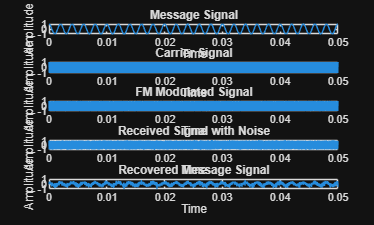

clc;
clear;
close all;

%% Parameters
fs = 100000;            % Sampling frequency
t = 0:1/fs:0.05;        % Time vector

fm = 500;               % Message frequency (Hz)
fc = 10000;             % Carrier frequency (Hz)
Am = 1;                 % Message amplitude
Ac = 1;                 % Carrier amplitude
kf = 2000;              % Frequency deviation constant

%% Message Signal
m = Am*cos(2*pi*fm*t);

%% Carrier Signal
c = Ac*cos(2*pi*fc*t);

%% FM Modulation
integral_m = cumsum(m)/fs;
s = Ac*cos(2*pi*fc*t + 2*pi*kf*integral_m);

%% Channel (Add Noise)
snr = 20;
r = awgn(s,snr,'measured');

%% FM Demodulation (Frequency Discriminator Method)

analytic_signal = hilbert(r);
inst_phase = unwrap(angle(analytic_signal));
inst_freq = diff(inst_phase)*fs/(2*pi);

recovered = inst_freq - fc;
recovered = [recovered recovered(end)];

%% Normalize recovered signal
recovered = recovered/max(abs(recovered));

%% Plotting

figure

subplot(5,1,1)
plot(t,m)
title('Message Signal')
xlabel('Time')
ylabel('Amplitude')

subplot(5,1,2)
plot(t,c)
title('Carrier Signal')
xlabel('Time')
ylabel('Amplitude')

subplot(5,1,3)
plot(t,s)
title('FM Modulated Signal')
xlabel('Time')
ylabel('Amplitude')

subplot(5,1,4)
plot(t,r)
title('Received Signal with Noise')
xlabel('Time')
ylabel('Amplitude')

subplot(5,1,5)
plot(t,recovered)
title('Recovered Message Signal')
xlabel('Time')
ylabel('Amplitude')

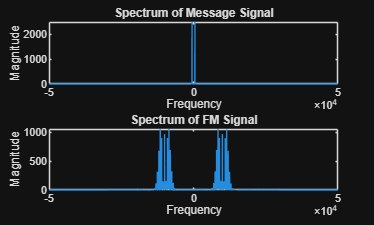


%% Frequency Spectrum

figure

N = length(s);
f = (-N/2:N/2-1)*(fs/N);

S = fftshift(abs(fft(s)));
M = fftshift(abs(fft(m)));

subplot(2,1,1)
plot(f,M)
title('Spectrum of Message Signal')
xlabel('Frequency')
ylabel('Magnitude')

subplot(2,1,2)
plot(f,S)
title('Spectrum of FM Signal')
xlabel('Frequency')
ylabel('Magnitude')